# **Optimized test space for projection**

Experiment with removing modes in the direction aligning with the Noise projected back to the subspace(LN), this will create a new subspace with the modes direction removed and act as a modified test space, this is somewhat similar to PG but here the test space is created by modifying the trail space instead of using the new data or data from different initial conditions.

## Settings

clear; close all; clc;
addpath(genpath('../1src'));

Re=1000; 
N=128; 
alpha=1; 
beta=0; 
meanInd=2;
dt=1e-2; 
K=15000;
r=8; k0=1;

seed  = 3001;
idx = [];            % empty -> use mid index

% ---- modes to remove
tail_idx = 7:8;      % use old tail columns to define bad directions
pbad     = 2;        % number of bad directions to remove in orthonormal LN

## Building Orr-Sommerfeld Operator.

OS_op is a function which generates the operator using the above settings. Orr-Sommerfeld is a linearized Navier Stokes equation, this setup is for a channel flow problem, with x and z are homogenous directions, represented by the fourier modes while the Y- direction perturbations are solved for, Chebychev nodes are used for the Y-direction discretization since we can have higher node density near the boundary where the no-slip condition is applied and sharp changes are expected. Due to the use of chebyshev nodes we have to introduce weighing function w.

[A,M,y] = OS_Op(alpha,beta,N,Re,meanInd);
n = size(A,1); % number of nodes
if isempty(idx), idx = round(n/2); end

L   = -1i*(M\A);      % full generator
Phi = expm(dt*L);     % full propagator

% Chebyshev quadrature weights (interior)
w  = clencurt_WeightsB(N);
W  = diag(sqrt(w));
W2 = diag(w);

### Generating the Clean Data.

This can be seen as analagous to the noise free experimental data.

%Random Initial COndition
q0 = randn(n,1);
%Normalized Initial Condition
q0 = q0 / norm(q0);

%Initializing the data matrix (Qf = Nodes x time)
Qf = zeros(n,K);
%Evolving the Initial Condition using the operator
%this is a linear time invarient system : qdot = A q
% q(t) = e^Adt q(0)

q = q0;
for k = 1:K
    q = Phi*q;
    Qf(:,k) = q;
end
t = (0:K-1)';

plot(real(Qf(:,k/2)));

### Adding Noise to the data.

Now we add Noise to the data, this will be analogous to the real experimental data which is prone to noise. Qf to Qf_N. The noise we are adding is Independent and Identically distributed (IID). Therefore the mean of the noise is zero and it doesnt shift the data. Since the nodes are non-uniform (Chebychev) the noise will be added in weighted space.

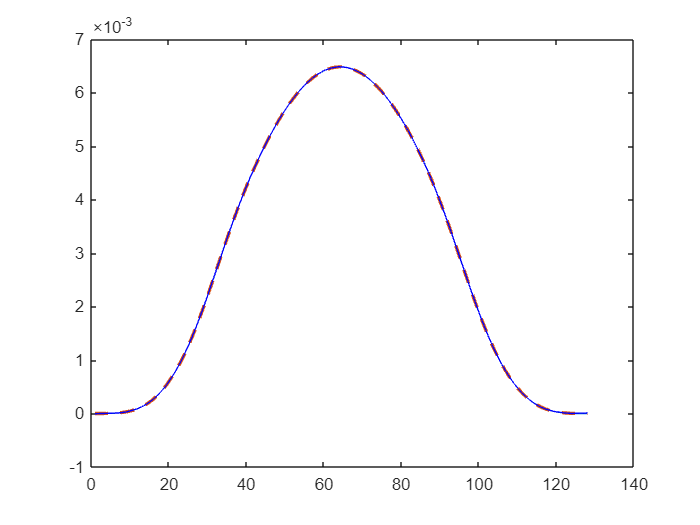

rng(seed);

Xw = W * Qf; %clean data in weighted space.
sigma_rel = 5e-5; % applied to the standard deviation
std_data = std(Xw(:)); %standard deviation of data
sigma = sigma_rel * std_data;
%fprintf('SIGMA = %.3e\n', sigma);

XwN = Xw + sigma * randn(size(Xw)); %Noisy data in weighted space
%randn is a unit noise with mean =0 and stdev =1)
QfN = W \ XwN; %Noisy data Matrix

% fprintf(' DATA NOISE: ||W(QfN-Qf)||F / ||WQf||F = %.3e\n', ...
%     norm(W*(QfN-Qf),'fro') / max(norm(W*Qf,'fro'), eps));
hold on;
plot(real(Qf(:,k/2)), '--', LineWidth=2);
plot(real(QfN(:,k/2)), 'b');
hold off;

### Modes Shift

Checking for the shift in modes after adding noise in data. So adding noise may shift as well as rotate the modes, so we need to align the noisy modes with the clean modes to find the true shift

%svd of clean data
[Uw,Sw,Vw] = svd(Xw,'econ');
U = W \ Uw;
%svd of noisy data
[Unw,Snw,Vnw] = svd(XwN,'econ');
Un = W \ Unw;
%

chkA = norm(Un' * W2 * Un - eye(size(Un)), 'fro');
fprintf('orth(noisy-data basis) = %.2e\n', chkA);

orth(noisy-data basis) = 2.03e-14


%if chkA is a small number Un is orthonormal in weighted space.


%Noise in modes
% Neff = Un - U;
% fprintf('||Neff||_F        = %.3e\n', norm(Neff,'fro'));
% fprintf('||Neff||_F/sqrt(r)= %.3e\n', norm(Neff,'fro')/sqrt(r));
% fprintf('max |Neff(:)|     = %.3e\n', max(abs(Neff(:))));
%This is not correct
%Adding noise rotates the subspace, now we first need to align modes
%with noise in rotated subspace to the clean mode and than find 
%the shift, this is called a orthogonal Procrustes Problem

G = U' * W2 * Un;
[Urot,~,Vrot] = svd(G,'econ');
R = Urot * Vrot';

Unrot = Un* R';
chkA1 = norm(Unrot' * W2 * Unrot - eye(size(Unrot)), 'fro');
fprintf('orth(aligned noisy-data) = %.2e\n', chkA1);

orth(aligned noisy-data) = 2.71e-14



% ---- Old perturbation
Neff = Unrot - U;

fprintf('||Neff||_F        = %.3e\n', norm(Neff,'fro'));

||Neff||_F        = 2.597e-13


fprintf('||Neff||_F/sqrt(r)= %.3e\n', norm(Neff,'fro')/sqrt(N));

||Neff||_F/sqrt(r)= 2.295e-14


fprintf('max |Neff(:)|     = %.3e\n', max(abs(Neff(:))));

max |Neff(:)|     = 2.869e-14




%noise is dependent on subspace choice so depends on choice of r.


## Clean ROM

rom0 = rom_build_clean(Qf, W, W2, L, r, alpha);
Ur0  = rom0.Ur;
S    = rom0.s;
%Orthogonality Check
chk0 = norm(Ur0' * W2 * Ur0 - eye(r), 'fro');
fprintf('orth(clean) = %.2e\n', chk0);

orth(clean) = 8.68e-16


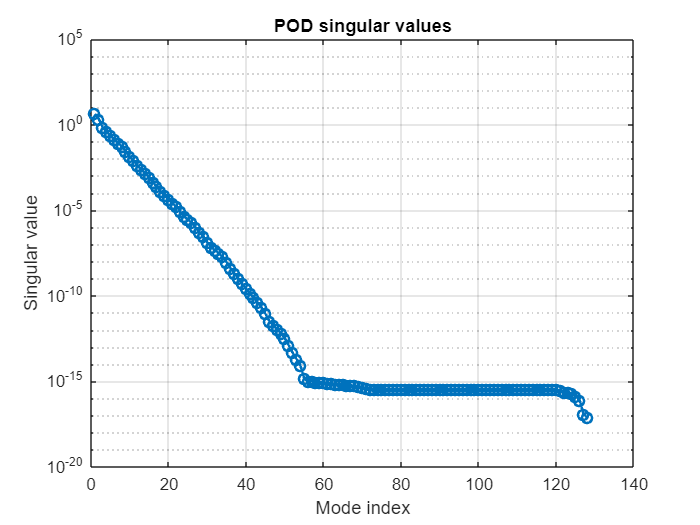

%Reduced operator (Atilde = Ur' W2 A Ur)
Lr0 = Ur0' * W2 * L * Ur0;
Pr0 = expm(dt * Lr0);

figure('Color','w');
semilogy(S,'o-','LineWidth',1.5);
xlabel('Mode index');
ylabel('Singular value');
title('POD singular values');
grid on;

### Noisy ROM

%rom built using noisy data QfN = Qf + Noise
romN = rom_build_clean(QfN, W, W2, L, r, alpha);
UrN  = romN.Ur;
sing_N = romN.s;

chkN = norm(UrN' * W2 * UrN - eye(r), 'fro');
fprintf('orth(noisy-data basis) = %.2e\n', chkN);

orth(noisy-data basis) = 1.02e-15



LrN = UrN' * W2 * L * UrN;
PrN = expm(dt * LrN);

%computing the noise in the modes (Note: noise depends on the selected
%subspace of r modes.)
% ---- Align noisy basis to clean basis
G = Ur0' * W2 * UrN;
[Urot,~,Vrot] = svd(G,'econ');
R = Urot * Vrot';

UrNa = UrN * R';
chkA = norm(UrNa' * W2 * UrNa - eye(r), 'fro');
fprintf('orth(aligned noisy-data) = %.2e\n', chkA);

orth(aligned noisy-data) = 3.45e-15



% ---- Rotate noisy reduced generator
LrNa = R * LrN * R';

% ---- Old perturbation
Neff = UrNa - Ur0;

fprintf('||Neff||_F        = %.3e\n', norm(Neff,'fro'));

||Neff||_F        = 5.711e-04


fprintf('||Neff||_F/sqrt(r)= %.3e\n', norm(Neff,'fro')/sqrt(r));

||Neff||_F/sqrt(r)= 2.019e-04


## Decomposition of the Reduced Operator.


$$L ̃r = (Ur + N)^* W2 L (Ur + N)  = [U_r^H W_2 *L *U_r ]  + [N^H* W_2 *L *U_r  ]  + [U_r^H  *W_2* L *N]    + [N^H*W_2* L *N  ] \\


A _0 =  U_r^H W_2 *L *U_r\\

A _1 =  N^H* W_2 *L *U_r\\

A_2 =  U_r^H  *W_2* L *N\\

A_3 = N^H*W_2* L *N 
$$


% ---- Old decomposition
A0 = Ur0'   * W2 * L * Ur0;
A1 = Neff'  * W2 * L * Ur0;
A2 = Ur0'   * W2 * L * Neff;
A3 = Neff'  * W2 * L * Neff;

Lr_sum = A0 + A1 + A2 + A3;
fprintf('\nDECOMP CHECK (aligned): ||LrNa - sum(Ak)||F = %.3e\n', ...
    norm(LrNa - Lr_sum,'fro'));


DECOMP CHECK (aligned): ||LrNa - sum(Ak)||F = 1.205e-13


## Identifying the effect of each term A1, A2 and A3 on the ROM accuracy.

The idea is to identify the dominant noise term out of these and how they effect the accuracy of noisy ROM.This

gives an idea regarding which term to use for noise correction.

% ---- Old "remove-term" ROMs
Lr_rmA1   = LrNa - A1;
Lr_rmA2   = LrNa - A2;
Lr_rmLIN  = LrNa - (A1 + A2);
Lr_rmQUAD = LrNa - A3;

PrNa      = expm(dt * LrNa);
Pr_rmA1   = expm(dt * Lr_rmA1);
Pr_rmA2   = expm(dt * Lr_rmA2);
Pr_rmLIN  = expm(dt * Lr_rmLIN);
Pr_rmQUAD = expm(dt * Lr_rmQUAD);


## Simulating these ROMs over time

Qr0       = roll_Pr(Pr0,       Ur0,  W2, Qf, k0);
QrN       = roll_Pr(PrNa,      UrNa, W2, Qf, k0);
%QrC       = roll_Pr(PrC,       UrNa, W2, Qf, k0);
Qr_rmA1   = roll_Pr(Pr_rmA1,   UrNa, W2, Qf, k0);
Qr_rmA2   = roll_Pr(Pr_rmA2,   UrNa, W2, Qf, k0);
Qr_rmLIN  = roll_Pr(Pr_rmLIN,  UrNa, W2, Qf, k0);
Qr_rmQUAD = roll_Pr(Pr_rmQUAD, UrNa, W2, Qf, k0);


## Plotting the ROMs solutions

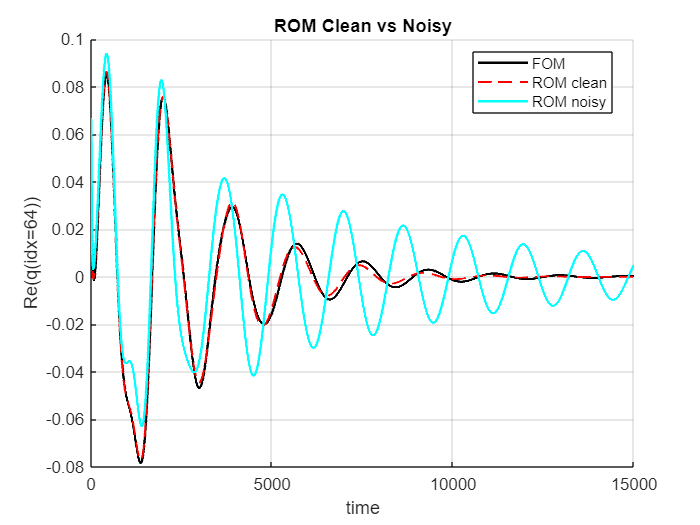

%  EXTRACT SINGLE-POINT TRAJECTORIES
% ============================================================

qf    = Qf(idx,:).';
q0i   = Qr0(idx,:).';
qNi   = QrN(idx,:).';
%qCi   = QrC(idx,:).';
qA1i = Qr_rmA1(idx,:).';
qA2i = Qr_rmA2(idx,:).';
qLNi = Qr_rmLIN(idx,:).';
qQDi = Qr_rmQUAD(idx,:).';


figure('Color','w');
hold on; grid on;
 plot(t, real(qf),  'k-',  'LineWidth',1.5, 'DisplayName','FOM');
 plot(t, real(q0i), 'r--',  'LineWidth',1.2, 'DisplayName','ROM clean');
 plot(t, real(qNi), 'c-',  'LineWidth',1.5, 'DisplayName','ROM noisy');
% plot(t, real(qCi), 'g--', 'LineWidth',1.8, 'DisplayName','ROM corrected');
% plot(t, real(qA1i),'g--', 'LineWidth',1.8, 'DisplayName','ROM (noisy - A1)');
% plot(t, real(qA2i),'c--', 'LineWidth',1.5, 'DisplayName','ROM (noisy - A2)');
% plot(t, real(qLNi),'k--', 'LineWidth',1.6, 'DisplayName','ROM (noisy - (A1+A2))');
% plot(t, real(qQDi),'r--', 'LineWidth',1.6, 'DisplayName','ROM (noisy - A3)');
xlabel('time');
ylabel(sprintf('Re(q(idx=%d))', idx));
title('ROM Clean vs Noisy');
legend('Location','best');

figure('Color','w');
hold on; grid on;
 %plot(t, real(qf),  'k-',  'LineWidth',1.5, 'DisplayName','FOM');
 plot(t, real(q0i), 'b--',  'LineWidth',1.2, 'DisplayName','ROM clean');
 %plot(t, real(qNi), 'c-',  'LineWidth',1.5, 'DisplayName','ROM noisy');
% plot(t, real(qCi), 'g--', 'LineWidth',1.8, 'DisplayName','ROM corrected');
 plot(t, real(qA1i),'g--', 'LineWidth',1.8, 'DisplayName','ROM (noisy - A1)');
plot(t, real(qA2i),'m--', 'LineWidth',1.5, 'DisplayName','ROM (noisy - A2)');
% plot(t, real(qLNi),'k--', 'LineWidth',1.6, 'DisplayName','ROM (noisy - (A1+A2))');
 plot(t, real(qQDi),'r--', 'LineWidth',1.6, 'DisplayName','ROM (noisy - A3)');
xlabel('time');
ylabel(sprintf('Re(q(idx=%d))', idx));
title(' decomposition : A1/A2/A3 removal on noisy ROM');
legend('Location','best');

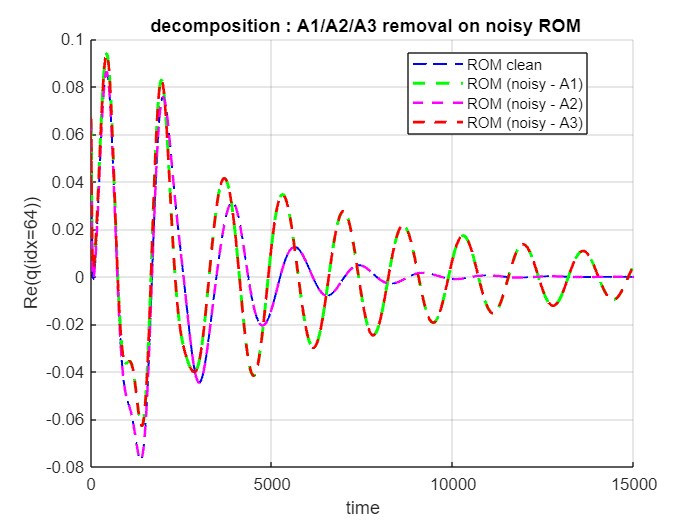

hold off;

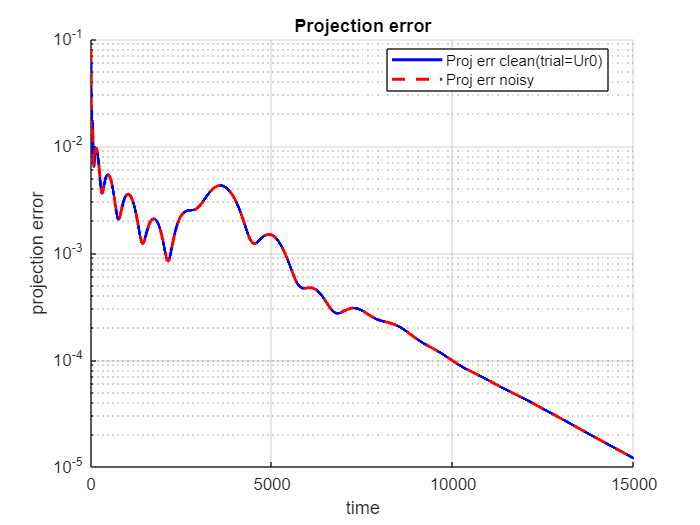

%Projection Error
% Projection errors
Ep0  = proj_err(Qf, Ur0,  W2, k0);
EpN  = proj_err(Qf, UrNa, W2, k0);

% Model errors
[Em0, rho0]       = model_err(Qf, Ur0,  W2, Pr0,       k0);
[EmN, rhoN]       = model_err(Qf, UrNa, W2, PrNa,      k0);
%[EmC, rhoC]       = model_err(Qf, UrNa, W2, PrC,       k0);
%[EmPG, rhoPG]     = model_err(Qf, UrNa,  W2, PrPG,      k0);

[Em_rmA1,   rho_rmA1]   = model_err(Qf, UrNa, W2, Pr_rmA1,   k0);
[Em_rmA2,   rho_rmA2]   = model_err(Qf, UrNa, W2, Pr_rmA2,   k0);
[Em_rmLIN,  rho_rmLIN]  = model_err(Qf, UrNa, W2, Pr_rmLIN,  k0);
[Em_rmQUAD, rho_rmQUAD] = model_err(Qf, UrNa, W2, Pr_rmQUAD, k0);


%plots
figure; hold on; grid on;
plot(t, max(Ep0,1e-16), 'b-',  'LineWidth',1.8, 'DisplayName','Proj err clean(trial=Ur0)');
plot(t, max(EpN,1e-16), 'r--', 'LineWidth',1.8, 'DisplayName','Proj err noisy');
%plot(t, max(EpPG,1e-16),'m-.', 'LineWidth',1.8, 'DisplayName','Proj err PG(trial=Ur0)');
xlabel('time'); ylabel('projection error');
title('Projection error');
legend('Location','best');
set(gca,'YScale','log'); 

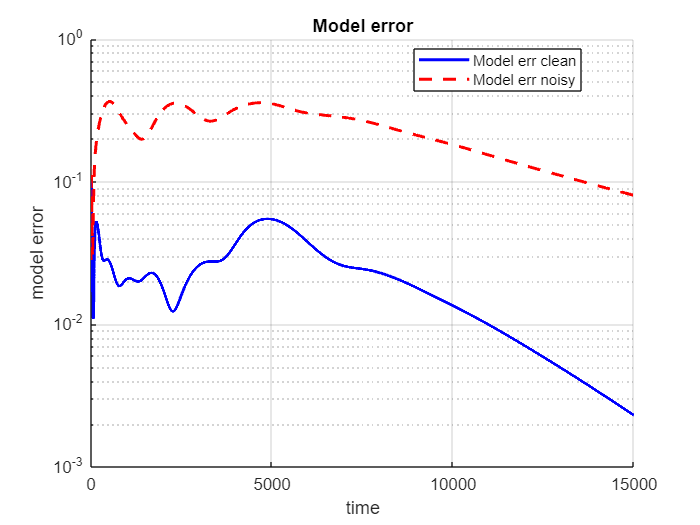


figure; hold on; grid on;
plot(t, max(Em0,1e-16), 'b-',  'LineWidth',1.8, 'DisplayName','Model err clean');
plot(t, max(EmN,1e-16), 'r--', 'LineWidth',1.8, 'DisplayName','Model err noisy');
%plot(t, max(EmPG,1e-16),'m-.', 'LineWidth',1.8, 'DisplayName','Model err PG');
xlabel('time'); ylabel('model error');
title('Model error');
legend('Location','best');
set(gca,'YScale','log');

## Error Calcs

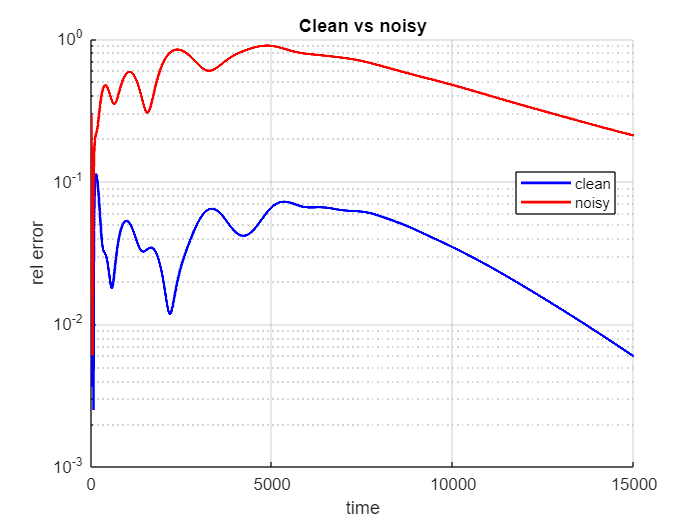

den_i = max(abs(qf(1)), 1e-14);
rel = @(x) abs(x - qf) ./ den_i;

e0i  = rel(q0i);
eNi  = rel(qNi);
%eCi  = rel(qCi);
%ePGi = rel(qPGi);
eA1i = rel(qA1i);
eA2i = rel(qA2i);
eLNi = rel(qLNi);
eQDi = rel(qQDi);

figure('Color','w');
hold on; grid on;
plot(t, max(e0i,1e-16), 'b-',  'LineWidth',1.6, 'DisplayName','clean');
plot(t, max(eNi,1e-16), 'r-',  'LineWidth',1.6, 'DisplayName','noisy');
xlabel('time'); ylabel('rel error');
title('Clean vs noisy');
legend('Location','best');
set(gca,'YScale','log');

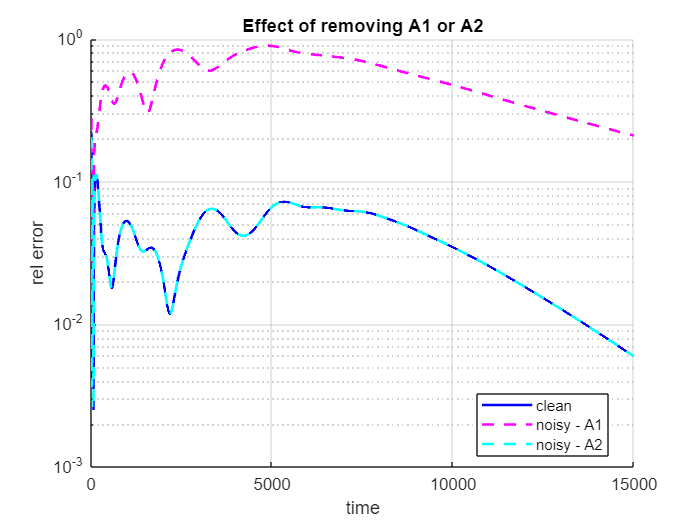

figure; hold on; grid on;
plot(t, max(e0i,1e-16),  'b-',  'LineWidth',1.6, 'DisplayName','clean');
plot(t, max(eA1i,1e-16), 'm--', 'LineWidth',1.6, 'DisplayName','noisy - A1');
plot(t, max(eA2i,1e-16), 'c--', 'LineWidth',1.6, 'DisplayName','noisy - A2');
xlabel('time'); ylabel('rel error');
title('Effect of removing A1 or A2');
legend('Location','best');
set(gca,'YScale','log');

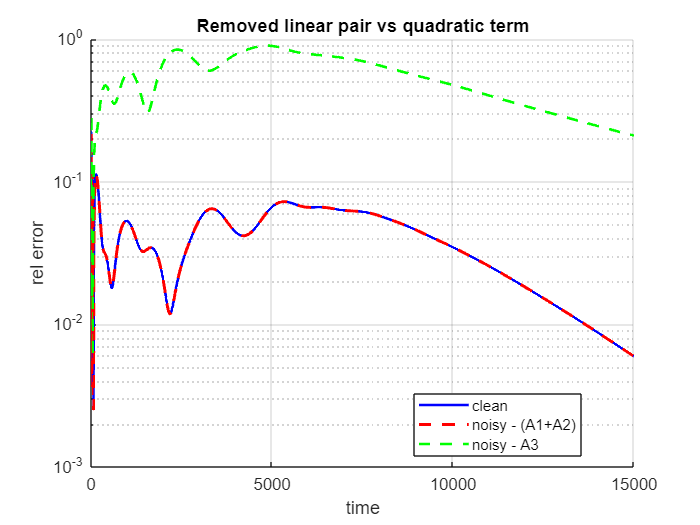

figure; hold on; grid on;
plot(t, max(e0i,1e-16),  'b-',  'LineWidth',1.6, 'DisplayName','clean');
plot(t, max(eLNi,1e-16), 'r--', 'LineWidth',1.8, 'DisplayName','noisy - (A1+A2)');
plot(t, max(eQDi,1e-16), 'g--', 'LineWidth',1.6, 'DisplayName','noisy - A3');
xlabel('time'); ylabel('rel error');
title('Removed linear pair vs quadratic term');
legend('Location','best');
set(gca,'YScale','log');

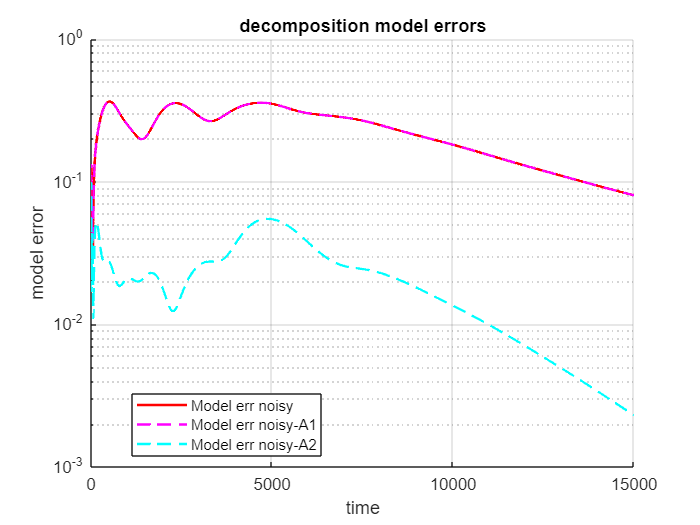

figure; hold on; grid on;
%plot(t, max(Em0,1e-16),      'b-',  'LineWidth',1.6, 'DisplayName','Model err clean');
plot(t, max(EmN,1e-16),      'r-',  'LineWidth',1.6, 'DisplayName','Model err noisy');
%plot(t, max(EmC,1e-16),      'g--', 'LineWidth',1.6, 'DisplayName','Model err corrected');
plot(t, max(Em_rmA1,1e-16),  'm--', 'LineWidth',1.4, 'DisplayName','Model err noisy-A1');
plot(t, max(Em_rmA2,1e-16),  'c--', 'LineWidth',1.4, 'DisplayName','Model err noisy-A2');
xlabel('time'); ylabel('model error');
title('decomposition model errors');
legend('Location','best');
set(gca,'YScale','log');

# Optimized Test Space for Projection

It is shown that the term A2 is the most significant term for error correction.


$$A_2 =  U_r^H  *W_2* L *N$$


We notice that here the operator L acts on the noise matrix N and projected in the mode direction or solution subspace.

So if we identiy the modes which are aligned with the LN and remove those modes from Ur , creating  a new subspace

which we use for the projection. Using this we can avoid the projection of noise back to the subspace and reducing the A2 term

effectively. (From previous analysis we identified that the tail end modes align with the LN )

% Dangerous directions tail only
LN = L * Neff; 
Bbad = LN(:,tail_idx); %vectors aligned with the tail end modes
Bw = W * Bbad; %weighted space
%Determining the orthogonal bad directions from the Bw vectors.
[Ubw,~,~] = svd(Bw,'econ');

% actual number of bad directions used; cannot exceed available independent bad directions from SVD
%Even if I selected 2 bad columns, they may collapse into only 1 actual bad
%direction. This protects this situation.
%pbad is the dominant direction from SVD of Bw, currently pbad = first 2
%dominant directions

pbad_eff = min([pbad, size(Ubw,2)]);


%back to state space
Vbad = W \ Ubw(:,1:pbad_eff);
Vbad = W2_orthonormalize(Vbad, W);

%How much noisy snapshot lie along each bad direction (proj of data along noisy
%dir) or projection coff
P_nd = Vbad'*W2*QfN;
%time snapshots of data component along bad directions
Q_bad = Vbad * P_nd;

%Noisy data with bad directions removed
QfNclean = QfN - Q_bad;
fprintf('||Vbad'' W2 Qclean||F = %.3e\n', norm(Vbad' * W2 * QfNclean,'fro'));

||Vbad' W2 Qclean||F = 9.064e-16


### Building Test space with the optimized subspace with bad directions removed.

% Build completely new POD basis from optimized noisy data
rom_new = rom_build_clean(QfNclean, W, W2, L, r, alpha);
Unew = rom_new.Ur;

chkUnew = norm(Unew' * W2 * Unew - eye(r), 'fro');
fprintf('orth(Unew) = %.2e\n', chkUnew);                                                                                                                    %

orth(Unew) = 9.25e-16


% Comparing  contamination seen by old vs new test basis
Cold = Ur0'  * W2 * (L * Neff);
Cnew = Unew' * W2 * (L * Neff);
fprintf('\nOld contamination seen by old vs new test basis:\n');


Old contamination seen by old vs new test basis:


fprintf('||Cold||F = %.6e\n', norm(Cold,'fro'));

||Cold||F = 6.784639e+00


fprintf('||Cnew||F = %.6e\n', norm(Cnew,'fro'));

||Cnew||F = 3.106558e-04


fprintf('ratio     = %.6e\n', norm(Cnew,'fro')/max(norm(Cold,'fro'),eps));

ratio     = 4.578812e-05


fprintf('max|Cold| = %.6e\n', max(abs(Cold(:))));

max|Cold| = 4.407901e+00


fprintf('max|Cnew| = %.6e\n', max(abs(Cnew(:))));

max|Cnew| = 1.889159e-04


#### ROM WITH OPTIMIZED TEST SPACE


$$\textrm{
}$$

$$L\textrm{̃}r=(U_{new}^H *W_2 *Un_r )^{-1} *(U_{new}^H *W_2 *L*Un_r )\textrm{
}$$


%trial = Ur0, test = Unew

Mr= Unew' * W2 * UrN;
Kr = Unew' * W2 * L   * UrN;

condMr = cond(Mr);
fprintf('\n mass matrix cond(Unew'' W2 Ur0) = %.6e\n', condMr);


 mass matrix cond(Unew' W2 Ur0) = 3.004150e+00



Lr = Mr \ Kr;
Pr = expm(dt * Lr);

%evolving dynamics
Qr = roll_Pr(Pr,UrN,  W2, QfN, k0);


eRRORS

[Em_new, rho]     = model_err(Qf, UrNa,  W2, Pr,k0);

Trajectory

q_newi  = Qr(idx,:).';

e_newi = rel(q_newi);

Plots

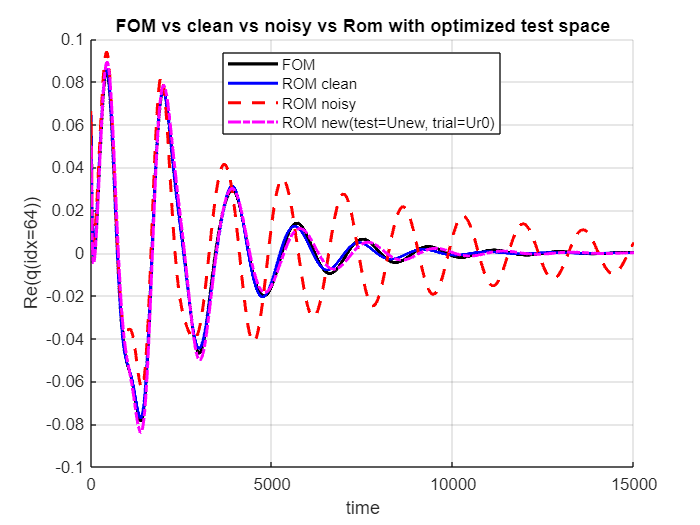

figure('Color','w');
hold on; grid on;
plot(t, real(qf),  'k-',  'LineWidth',2.0, 'DisplayName','FOM');
plot(t, real(q0i), 'b-',  'LineWidth',1.8, 'DisplayName','ROM clean');
plot(t, real(qNi), 'r--', 'LineWidth',1.8, 'DisplayName','ROM noisy');
plot(t, real(q_newi),'m-.', 'LineWidth',1.8, 'DisplayName','ROM new(test=Unew, trial=Ur0)');
xlabel('time');
ylabel(sprintf('Re(q(idx=%d))', idx));
title('FOM vs clean vs noisy vs Rom with optimized test space');
legend('Location','best');

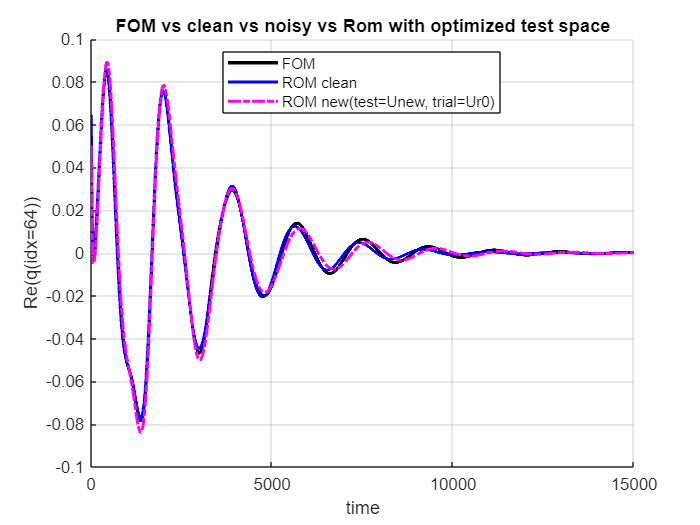

figure('Color','w');
hold on; grid on;
plot(t, real(qf),  'k-',  'LineWidth',2.0, 'DisplayName','FOM');
plot(t, real(q0i), 'b-',  'LineWidth',1.8, 'DisplayName','ROM clean');
% plot(t, real(qNi), 'r--', 'LineWidth',1.8, 'DisplayName','ROM noisy');
plot(t, real(q_newi),'m-.', 'LineWidth',1.8, 'DisplayName','ROM new(test=Unew, trial=Ur0)');
xlabel('time');
ylabel(sprintf('Re(q(idx=%d))', idx));
title('FOM vs clean vs noisy vs Rom with optimized test space');
legend('Location','best');

Comparisonbetween Clean ROM and oprimized Noisy ROM

figure('Color','w');
hold on; grid on;
%plot(t, real(qf),  'k-',  'LineWidth',2.0, 'DisplayName','FOM');
plot(t, real(q0i), 'b-',  'LineWidth',1.8, 'DisplayName','ROM clean');
%plot(t, real(qNi), 'r--', 'LineWidth',1.8, 'DisplayName','ROM noisy');
plot(t, real(q_newi),'m-.', 'LineWidth',1.8, 'DisplayName','ROM new(test=Unew, trial=Ur0)');
xlabel('time');
ylabel(sprintf('Re(q(idx=%d))', idx));
title(' Clean ROM vs Rom with optimized test space');
legend('Location','best');

**Model Error Comparison**

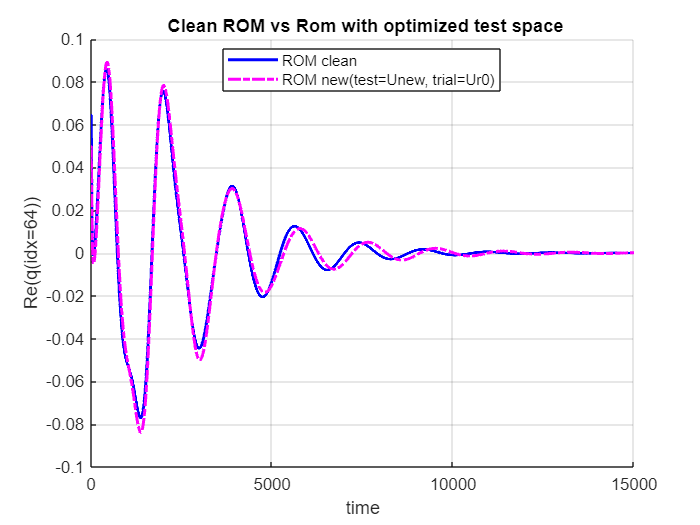

nexttile; hold on; grid on;

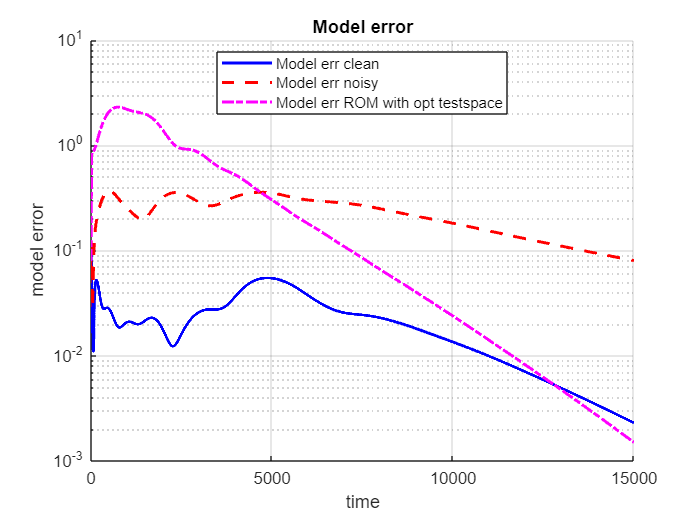

plot(t, max(Em0,1e-16), 'b-',  'LineWidth',1.8, 'DisplayName','Model err clean');
plot(t, max(EmN,1e-16), 'r--', 'LineWidth',1.8, 'DisplayName','Model err noisy');
plot(t, max(Em_new,1e-16),'m-.', 'LineWidth',1.8, 'DisplayName','Model err ROM with opt testspace');
xlabel('time'); ylabel('model error');
title('Model error');
legend('Location','best');
set(gca,'YScale','log');